% Número de puntos y variables independientes
n = input('Número de puntos: ');
m = input('Número de variables independientes: ');

% Inicializar matriz de variables independientes X y vector de Y
X_multiple = zeros(n, m); 
Y_multiple = zeros(n, 1);

% Ingresar valores de X y Y
for i = 1:n
    for j = 1:m
        X_multiple(i, j) = input(['X' num2str(j) '(' num2str(i) '): ']);
    end
    Y_multiple(i) = input(['Y(' num2str(i) '): ']);
end

% Construir la matriz A para el modelo lineal múltiple
A_multiple = [ones(n, 1), X_multiple];

% Calcular la fórmula de ajuste para el modelo múltiple
At_multiple = A_multiple'; % Transpuesta de A_multiple
AtA_multiple = At_multiple * A_multiple; % A' * A
AtA_inv_multiple = inv(AtA_multiple); % Inversa de (A' * A)
AtY_multiple = At_multiple * Y_multiple; % A' * Y
u_multiple = AtA_inv_multiple * AtY_multiple; % Coeficientes del modelo múltiple

% Mostrar los coeficientes
disp('Coeficientes del modelo lineal múltiple:');

Coeficientes del modelo lineal múltiple:


disp(u_multiple);

   -5.4611
    0.8623
    2.1737




% Evaluar Y_hat para el modelo lineal múltiple
Y_hat_multiple = A_multiple * u_multiple;

% ECM para el modelo múltiple
ECM_multiple = sum((Y_multiple - Y_hat_multiple).^2) / n;

% Mostrar el ECM
disp(['Error Cuadrático Medio (ECM) - Modelo Lineal Múltiple: ' num2str(ECM_multiple)]);

Error Cuadrático Medio (ECM) - Modelo Lineal Múltiple: 1.1976


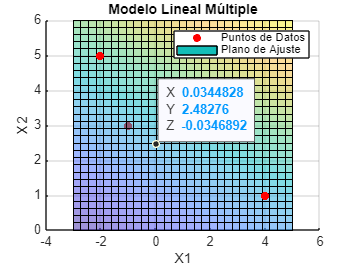


% ---------- GRAFICAR RESULTADOS PARA DOS VARIABLES INDEPENDIENTES ----------

if m == 2
    % Crear una figura
    figure;
    
    % Crear una malla para graficar el plano ajustado
    [X1, X2] = meshgrid(linspace(min(X_multiple(:,1)) - 1, max(X_multiple(:,1)) + 1, 30), ...
                        linspace(min(X_multiple(:,2)) - 1, max(X_multiple(:,2)) + 1, 30));
    
    % Calcular Y_hat para la malla
    Y_mesh = u_multiple(1) + u_multiple(2) * X1 + u_multiple(3) * X2;
    
    % Graficar los datos y el plano ajustado
    hold on;
    scatter3(X_multiple(:,1), X_multiple(:,2), Y_multiple, 'ro', 'filled', 'DisplayName', 'Puntos de Datos');
    surf(X1, X2, Y_mesh, 'FaceAlpha', 0.5, 'DisplayName', 'Plano de Ajuste');
    xlabel('X1');
    ylabel('X2');
    zlabel('Y');
    title('Modelo Lineal Múltiple');
    legend('show');
    grid on;
else
    disp('La visualización gráfica solo está disponible para modelos con dos variables independientes.');
end